# Some Imp. information

clear
clc
no_of_bits =10000;
vcc=1.2;
gnd=0;
t_step=0.01;
time=[0:t_step:no_of_bits-t_step];
sigma=linspace(0,vcc,10);

## UNIPOLAR-NRZ

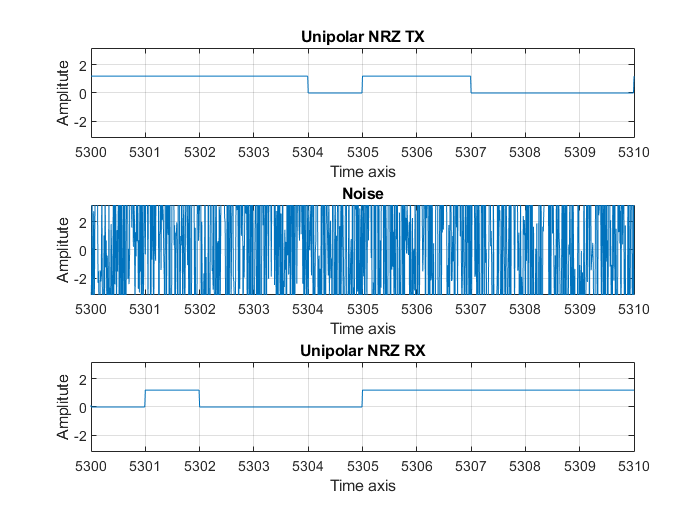

stream_of_bit=randi([0 1],1,no_of_bits);
line_coding=stream_of_bit.*vcc;
for i=1:no_of_bits
    for j=1:100
        line_coding_afetr_modification((i-1)*100+j)=line_coding(i);
    end
    
end
subplot(3,1,1);
plot(time,line_coding_afetr_modification);
axis([0 length(line_coding) -(vcc+2) (vcc+2)]);
xlabel("Time axis");
ylabel("Amplitute");
title("Unipolar NRZ TX");
grid on;
xlim([5300 5310]);
noise=line_coding_afetr_modification + (factor(7)*randn(size(line_coding_afetr_modification)));
subplot(3,1,2);
plot(time,noise);
axis([0 length(line_coding) -(vcc+2) (vcc+2)]);
xlabel("Time axis");
ylabel("Amplitute");
title("Noise");
grid on;
xlim([5300 5310]);
c=0;
for i=50:100: length(noise)
    if(noise(i)>0.6)
        for k=1:100
           RX_UP_NRZ(k+c)=vcc; 
        end
    else
        for k=1:100
        RX_UP_NRZ(k+c)=0;
        end
    end
    c=c+100;
end
subplot(3,1,3);
plot(time,RX_UP_NRZ);
axis([0 length(line_coding) -(vcc+2) (vcc+2)]);
xlabel("Time axis");
ylabel("Amplitute");
title("Unipolar NRZ RX");
grid on;
xlim([5300 5310]);

error=0;
for i=1:length(RX_UP_NRZ)
    if(RX_UP_NRZ(i)==line_coding_afetr_modification(i))
        continue
    else
        error=error+1;
    end
    
end
BEP=error/100/no_of_bits*100

BEP = 45.8900